# Waldo Finder

https://github.com/gabrielrodriguesrocha/waldofinder

Autores: Breno Vinicius Viana de Oliveira - 726498 (1) Gabriel Rodrigues Rocha - 726518 (2) Henrique Shinki Kodama - 726537 (3)

## Contato

(1) [breno.oliveira@dcomp.sor.ufscar.br](mailto:breno.oliveira@dcomp.sor.ufscar.br) (2) [gabrielrocha.comp@gmail.com](mailto:gabrielrocha.comp@gmail.com) (3) [hskodama@gmail.com](mailto:hskodama@gmail.com)

## Ínicio

Limpeza do ambiente

clc, clear, close all;

## Abertura das imagens

tic
scenario = 'scenarios/wheresWaldo4.jpg';
reference = dir('references/*.jpg');

% Imagem cenário
image = imread(scenario);
[ih, iw, ~] = size(image);

% Imagens de referência
files = {reference.name};
ref = cell(1,numel(files));
for k=1:numel(files)
    ref{k} = imread(strcat('references/',files{k}));
    ref{k} = rgb2gray(ref{k});
end

% Obtenção do tamanho do Waldo
waldo_size = 0;
for k = 1:numel(ref)
    waldo_size = waldo_size + mean(size(ref{k}))/numel(ref);
end

% Conversão da imagem cenário de RGB para HSV
imageHsv = rgb2hsv(image);
h = imageHsv(:, :, 1);
s = imageHsv(:, :, 2);
v = imageHsv(:, :, 3);

Segmentação por meio de cor

redStripes = ((h < 0.01) | (h > 0.9)) & (s > 0.7) & (v > 0.9);
whiteStripes = (s < 0.2) & (v > 0.9);

Criação de elemento estruturante: linha vertical

se = strel('line', waldo_size * 0.15, 90);

Dilatação das listras verticalmente

redDilated = imdilate(redStripes, se);
whiteDilated = imdilate(whiteStripes, se);

Obtenção da área sobreposta das listras

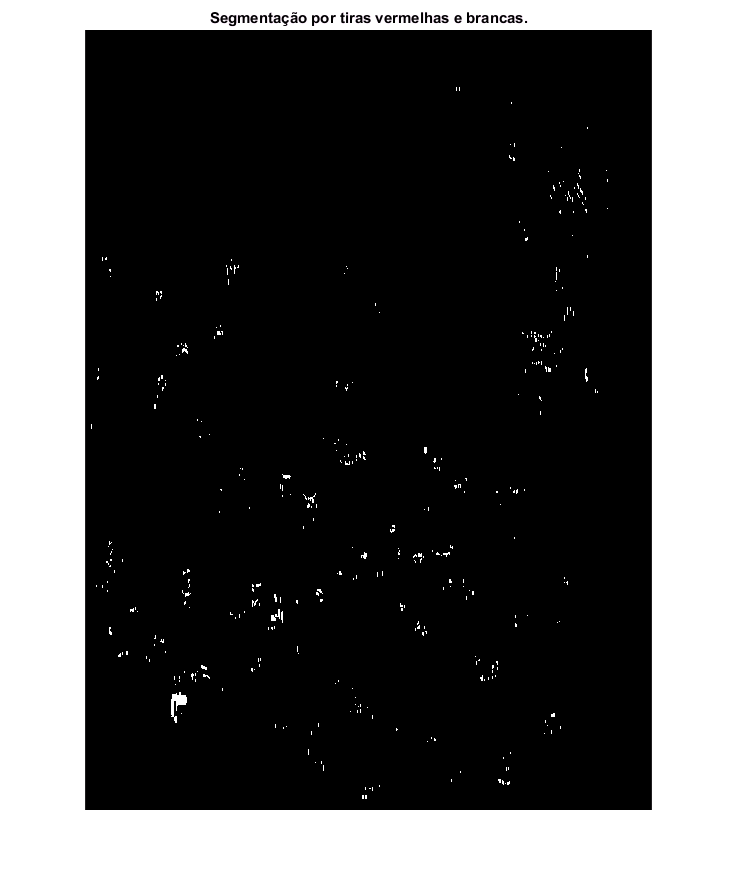

roi = redDilated & whiteDilated;
figure,imshow(roi), title('Segmentação por tiras vermelhas e brancas.');

Remoção de elementos menores ou maiores que não são o Waldo

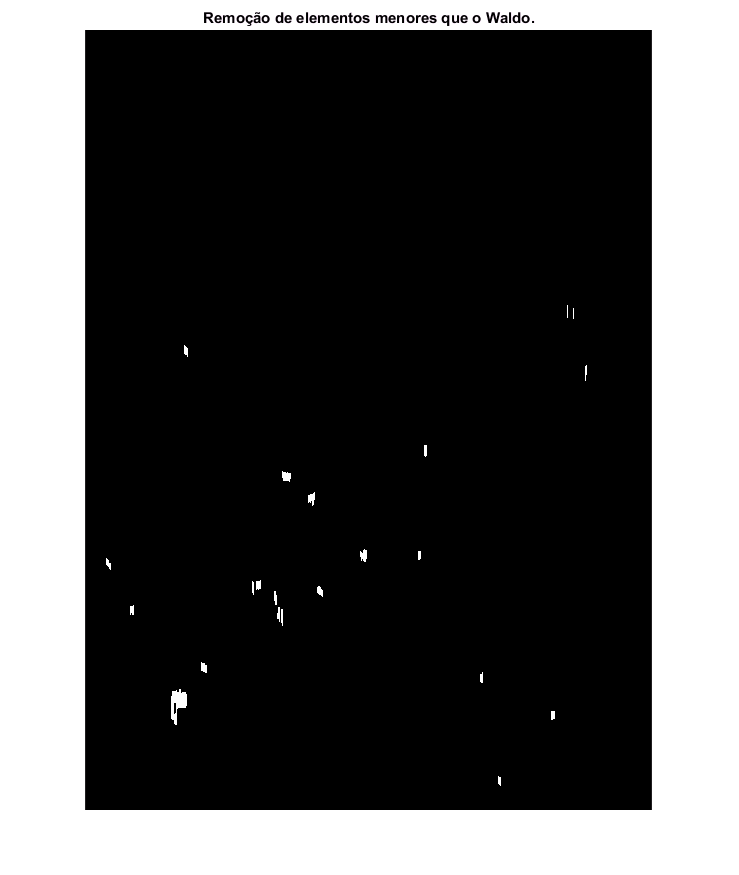

rg = regionprops(roi, 'Centroid');
if numel(rg) <= 10 % Tratamento de caso em que o Waldo é muito pequeno
    roi = imdilate(roi, strel('square', round(waldo_size * 0.1)));
end
roi = bwareaopen(roi, floor(waldo_size * 0.9));
roi = imdilate(roi, se);
roi = bwareaopen(roi, 20);
bigger = bwareaopen(roi, floor(25 * waldo_size));
roi = roi - bigger;
figure,imshow(roi), title('Remoção de elementos menores que o Waldo.');

Remoção de ruído dos objetos resultantes

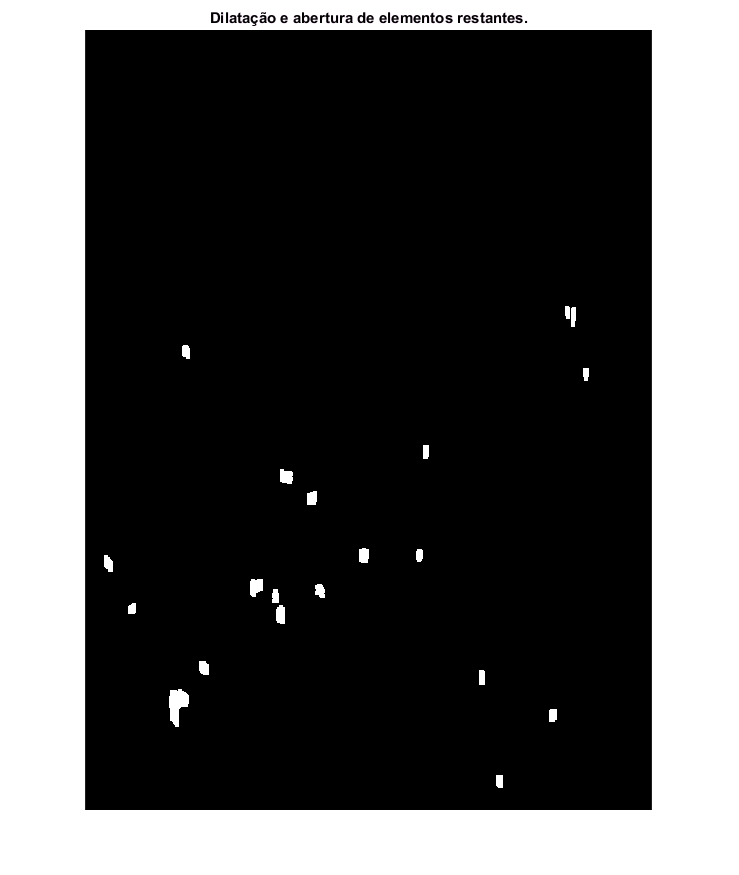

roi = roi & (redStripes | whiteStripes);
roi = imdilate(roi, strel('square', round(waldo_size * 0.1)));
roi = bwareaopen(roi, 12);
figure,imshow(roi), title('Dilatação e abertura de elementos restantes.');

Obtenção dos centroides da imagem

roi = logical(roi);
c = regionprops(roi, 'Centroid');
centroids = cat(1, c.Centroid);
locus_x = round(centroids(:,2));
locus_y = round(centroids(:,1));

x = size(centroids);
sizeref = size(ref);

Busca por Waldo através de iteração e correlação cruzada normalizada

color_image = image;
image = rgb2gray(image);

for i = 1:x(1)
    % Obtenção de um pedaço de interesse
    slice = cell(1,numel(ref));
    slice = cellfun(@(x) (image(max(1, locus_x(i)-100):min(ih, locus_x(i)+100), max(1, locus_y(i)-100):min(iw, locus_y(i)+100))), slice, 'UniformOutput', false);
    
    % Cálculo da correlação normalizada cruzada
    a = cellfun(@size, ref, 'UniformOutput', false);
    b = cellfun(@size, slice, 'UniformOutput', false);
    c = (cell2mat(a) < cell2mat(b));
    if c(:)
        res = cellfun(@normxcorr2, ref, slice, 'UniformOutput', false);
        % Obtenção de pontos máximos
        maxes = cell2mat(cellfun(@(x) (max(x(:))), res, 'UniformOutput', false));
    end
    
    if ~exist('cmax','var') % Caso em que nada foi calculado ainda
        cmax = maxes;
    	coords = [locus_x(i), locus_y(i)];
    elseif sum(cmax) < sum(maxes) % Caso em que um ponto maior que o maior anterior foi obtido
        cmax = maxes;
        coords = [locus_x(i), locus_y(i)];
    end
    
end

Todos os centroides e a região em que Waldo se encontra

figure,imshow(color_image),title('Centroides da imagem e Waldo.');

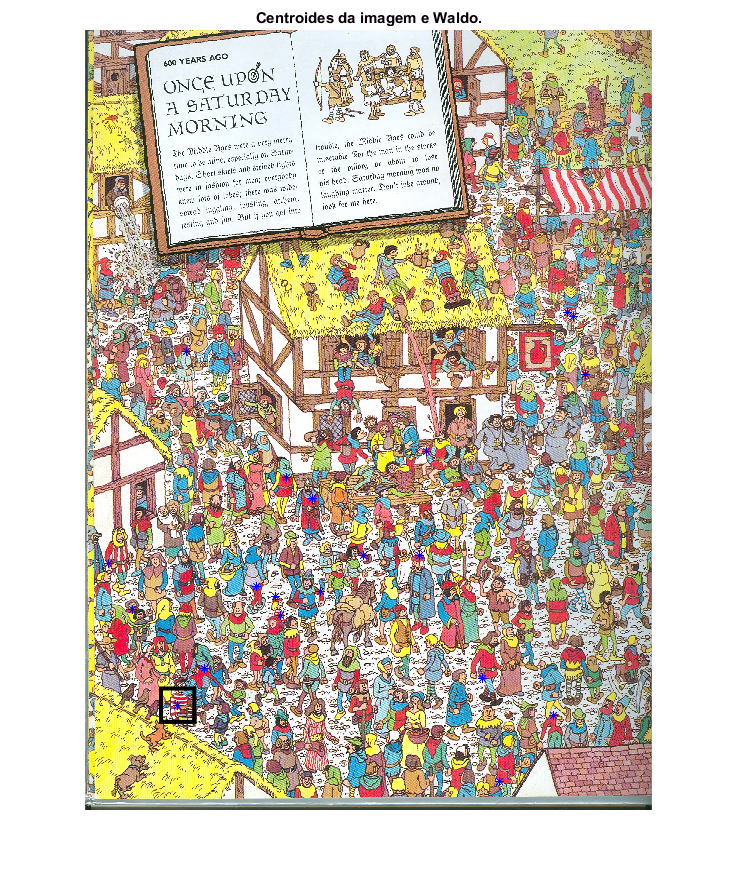

hold on
plot(centroids(:,1),centroids(:,2),'b*');
rectangle('Position', [coords(2)-50, coords(1)-50, 100, 100], 'LineWidth', 3);
hold off

Imagem ampliada de Waldo na imagem cenário

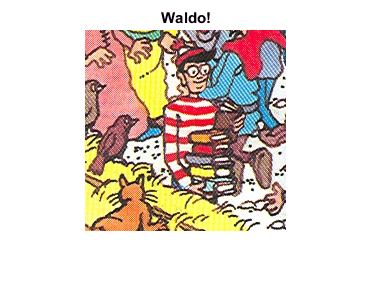

waldo = color_image(max(1,coords(1)-100):min(ih, coords(1)+100), max(1,coords(2)-100):min(iw, coords(2)+100), :);
figure,imshow(waldo), title('Waldo!');

toc

Elapsed time is 13.376429 seconds.
